
distance_map = zeros(16,16);

for n = 1:1:16
    for m = 1:1:16
        distance_map(n,m) = manhat(n,m,9,9);
    end
end



%distance_map(16,16) = manhat(n,m,9,9);

%distance_map
%figure; imagesc(distance_map);

shortwaves = waves(1:16:256,1:16:256);
figure; 
imagesc(shortwaves);

for k = 0:1:16
    lowpassed = lowpassFilter(shortwaves,distance_map,k);
    k
    rec = ifft2(lowpassed);
    figure; imagesc(real(rec));
    figure; imagesc(abs(shortwaves-real(rec)));
end

%mask = (distance_map <= k);

% ftwaves = fft2(waves);
% 
% figure; imagesc(waves);
% 
% plot(abs(ftwaves(125,:)));
% 
% shiftedftwaves = fftshift(ftwaves);
% 
% plot(abs(shiftedftwaves(125,:)));
% 

% 
% shortftwaves = fft2(shortwaves);
% 
% figure; imagesc(shortwaves);
% 
% %plot(abs(shortftwaves(8,:)));
% 
% shiftedshortftwaves = fftshift(shortftwaves);
% 
% %plot(abs(shiftedshortftwaves(8,:)));
% 
% ftshortwaves0 = shiftedshortftwaves .* mask;
% 
% figure; imagesc(ifft2(fftshift(ftshortwaves0)))


%mask = (distance_map <= k);
%M = M .* mask;
%figure; imagesc(distance_map);


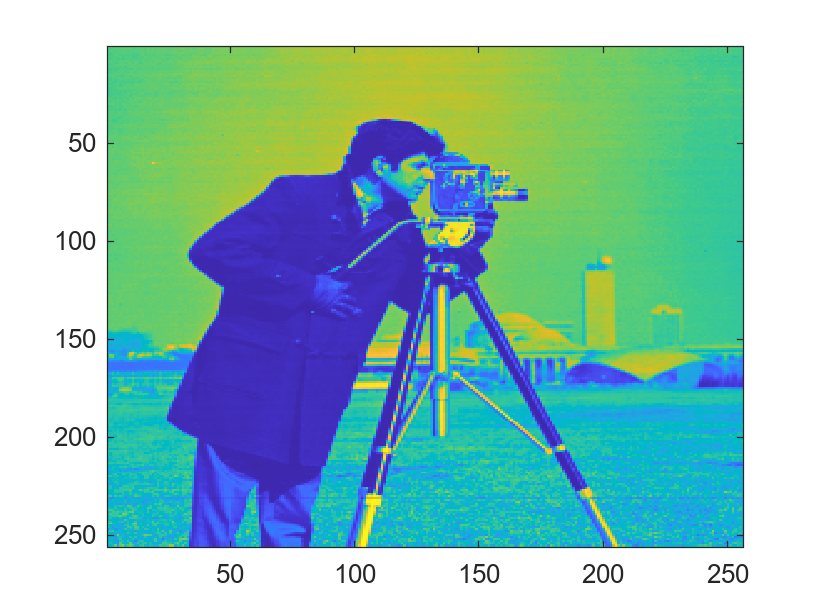

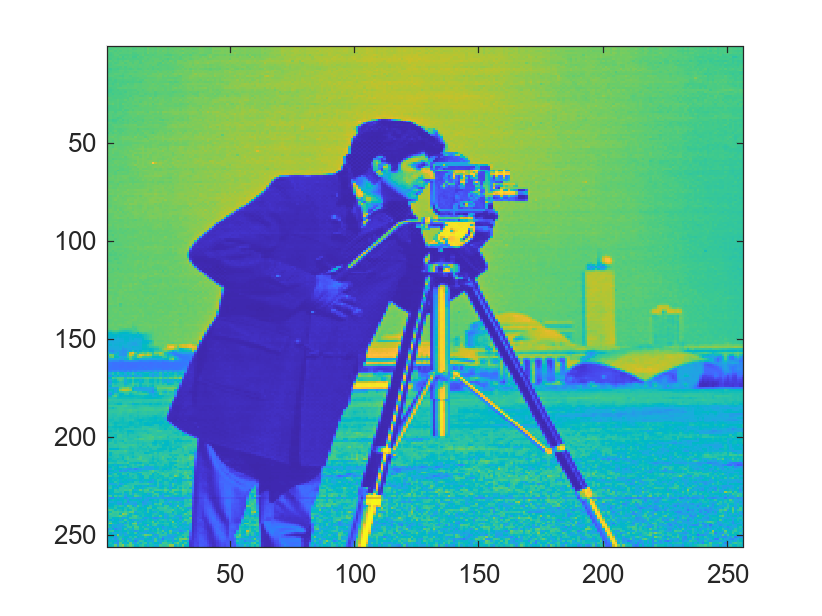

ORIGIM = imread('cameraman.tif');
ORIGIM = double(ORIGM);


distance_map = zeros(16,16);

for n = 1:1:16
    for m = 1:1:16
        distance_map(n,m) = manhat(n,m,9,9);
    end
end

%Delar up
SFFTIMAGE = complex(zeros(size(ORIGIM)));
for k  = 1:16:size(ORIGIM,1)-15
 for m = 1:16:size(ORIGIM,2)-15
  SFFTIMAGE(k:k+15,m:m+15)=fftshift(fft2(ORIGIM(k:k+15,m:m+15)));
 end
end

mask = (distance_map);

for mthres = 1:max(mask(:))
 for k  = 1:16:size(ORIGIM,1)-15
  for m = 1:16:size(ORIGIM,2)-15
    RECIM = ifft2(fftshift(SFFTIMAGE(k:k+15,m:m+15) .*(distance_map <= mthres -1)));
%   select the correct subimage from SFFTIMAGE   
%   mask, shift and inverse transform. Store result in  RECIMAGE
    RECIMAGE(k:k+15,m:m+15) = abs(RECIM);
  end
 end
 figure(1);imagesc(ORIGIM)
 figure(2);imagesc(RECIMAGE);
 drawnow
end